# **Decimation and Interpolation of Audio Signals   **

Multirate Digital Signal Processing- EE6133

Experiment 1

Author: Arjun Menon Vadakkeveedu, ee18b104

October 2021

## Part 1

#### 1.1 Read input files, play back and plot Magnitude Response

[audio16k, Fs_audio] = audioread('inp/music16khz.wav');
[speech8k, Fs_speech] = audioread('inp/speech8khz.wav');
disp(['Original Audio Signal Sampling Rate: ', num2str(Fs_audio), 'Hz']);

Original Audio Signal Sampling Rate: 16000Hz


disp(['Original Speech Signal Sampling Rate: ', num2str(Fs_speech), 'Hz']);

Original Speech Signal Sampling Rate: 8000Hz


% Playing the .wav files at original Sampling Rates
player1 = audioplayer(audio16k, Fs_audio);
player2 = audioplayer(speech8k, Fs_speech);
playblocking(player1);
playblocking(player2);

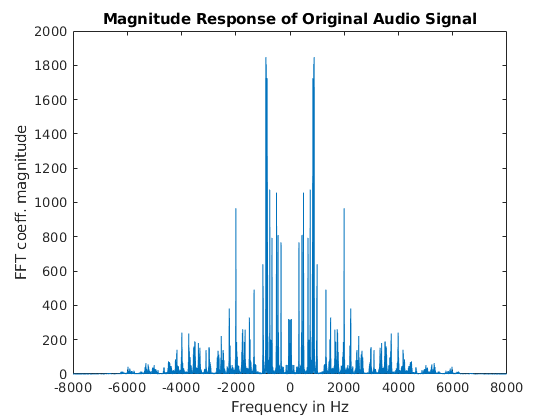

%Magnitude Response of Original Signals
Naudio = 2^(ceil(log2(length(audio16k))));
Nspeech = 2^(ceil(log2(length(speech8k))));
fft_audio = fftshift(fft(audio16k, Naudio));
fft_speech = fftshift(fft(speech8k, Nspeech));
wAudio = linspace(-Fs_audio/2, Fs_audio/2, Naudio);
wSpeech = linspace(-Fs_speech/2, Fs_speech/2, Nspeech); 
figure();
plot(wAudio, abs(fft_audio));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Response of Original Audio Signal");

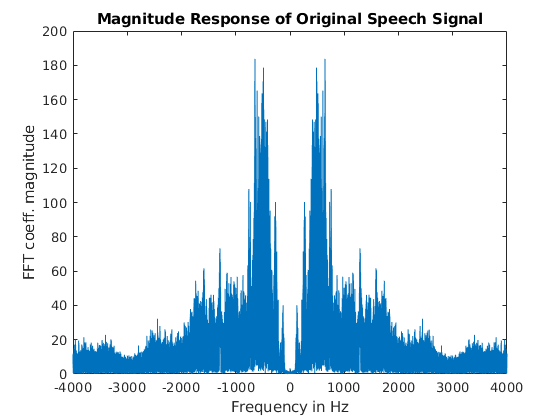

figure();
plot(wSpeech, abs(fft_speech));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Response of Original Speech Signal");

#### 1.2 Downsample by 2, play back and generate Magnitude Response

The generated audio files are saved to the location out/<originalFileName>-D2.wav

The signal {x[n]} is downsampled as

 $\{x_d[n]\} = x[Mn]

$, where M is the downsampling factor

%Downsampling by 2
audioD2 = audio16k(1:2:end);
speechD2 = speech8k(1:2:end);
Fs_audioD2 = Fs_audio/2;
Fs_speechD2 = Fs_speech/2;
player1 = audioplayer(audioD2, Fs_audioD2);
player2 = audioplayer(speechD2, Fs_speechD2);
playblocking(player1);
playblocking(player2);
audiowrite('out/music16k-D2.wav', audioD2, Fs_audioD2);
audiowrite('out/speech8k-D2.wav', speechD2, Fs_speechD2);

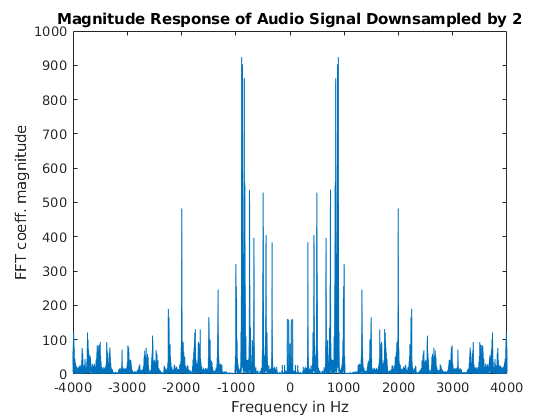

%Magnitude Response of Original Signals
NaudioD2 = 2^(ceil(log2(length(audioD2))));
NspeechD2 = 2^(ceil(log2(length(speechD2))));
fft_audioD2 = fftshift(fft(audioD2, NaudioD2));
fft_speechD2 = fftshift(fft(speechD2, NspeechD2));
wAudio = linspace(-Fs_audioD2/2, Fs_audioD2/2, NaudioD2);
wSpeech = linspace(-Fs_speechD2/2, Fs_speechD2/2, NspeechD2); 
figure();
plot(wAudio, abs(fft_audioD2));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Response of Audio Signal Downsampled by 2");

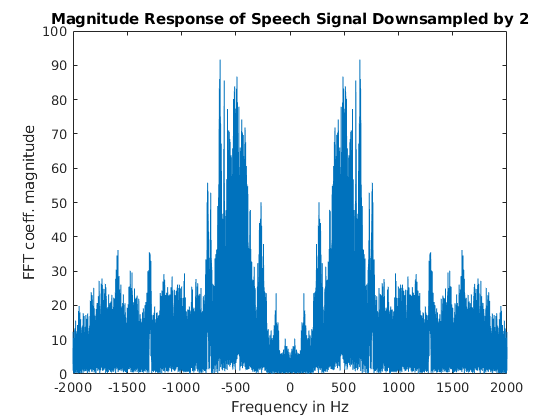

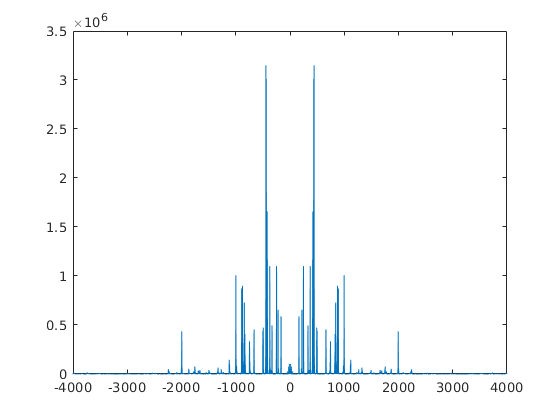

figure();
plot(wSpeech, abs(fft_speechD2));
xlabel("Frequency in Hz");
ylabel("FFT coeff. magnitude");
title("Magnitude Response of Speech Signal Downsampled by 2");